clear all
the = 30

the = 30

R = [cosd(the) -sind(the);
    sind(the) cosd(the)]

R =     0.8660   -0.5000
    0.5000    0.8660


x = [1;1]

x =      1
     1


x_t = R * x

x_t =     0.3660
    1.3660


figure
plot(x(1), x(2),'.')
hold on
plot(x_t(1), x_t(2), '*')
xlim([-1 3])
ylim([-1 3])
xL = xlim;
yL = ylim;
line([0 2], [0 0]);  %x-axis
line([0 0], [0 2]);  %x-axis

axiss_x =[2;0]

axiss_x =      2
     0


axiss_y = [0;2]

axiss_y =      0
     2


new_axiss_x = R * axiss_x

new_axiss_x =     1.7321
    1.0000


new_axiss_y = R * axiss_y

new_axiss_y =    -1.0000
    1.7321


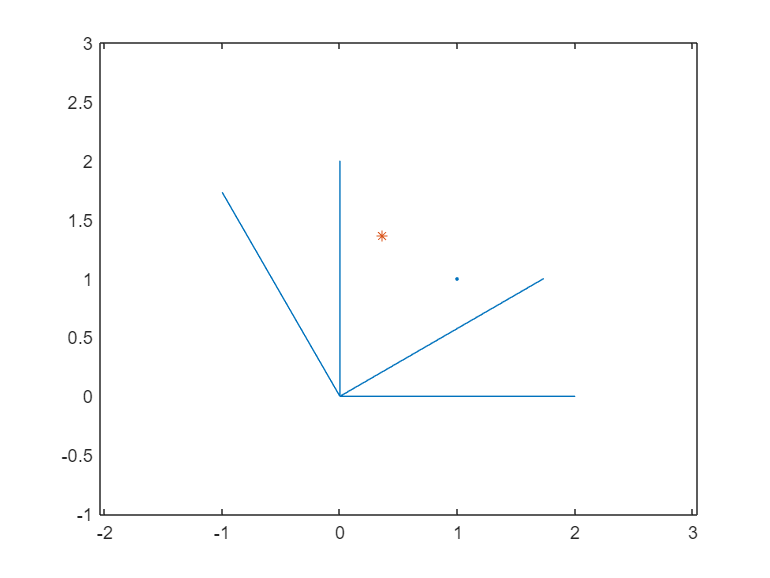


line([0 new_axiss_x(1)], [0 new_axiss_x(2)]);  %x-axis
line([0 new_axiss_y(1)], [0 new_axiss_y(2)]);  %x-axis
axis equal

the = 30

the = 30

R = [cosd(the) -sind(the);
    sind(the) cosd(the)]

R =     0.8660   -0.5000
    0.5000    0.8660


R * R

ans =     0.5000   -0.8660
    0.8660    0.5000


syms phi theta psi
t = theta

$$t = \theta$$

Rx = [1 0 0;
      0 cos(t) -sin(t);
      0 sin(t) cos(t)]

$$Rx = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\theta \right) & -\sin\left(\theta \right)\\ 0 & \sin\left(\theta \right) & \cos\left(\theta \right) \end{array}\right)$$

t = phi

$$t = \varphi$$

Ry = [cos(t) 0 sin(t);
     0 1 0;
     -sin(t) 0 cos(t)]

$$Ry = \left(\begin{array}{ccc} \cos\left(\varphi \right) & 0 & \sin\left(\varphi \right)\\ 0 & 1 & 0\\ -\sin\left(\varphi \right) & 0 & \cos\left(\varphi \right) \end{array}\right)$$

t = psi

$$t = \psi$$

Rz_psi = [cos(t) -sin(t) 0;
    sin(t) cos(t) 0;
    0 0 1]

$$Rz\_psi = \left(\begin{array}{ccc} \cos\left(\psi \right) & -\sin\left(\psi \right) & 0\\ \sin\left(\psi \right) & \cos\left(\psi \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

t = phi

$$t = \varphi$$

Rz_phi = [cos(t) -sin(t) 0;
    sin(t) cos(t) 0;
    0 0 1]

$$Rz\_phi = \left(\begin{array}{ccc} \cos\left(\varphi \right) & -\sin\left(\varphi \right) & 0\\ \sin\left(\varphi \right) & \cos\left(\varphi \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R = Rz_psi * Rx * Rz_phi

$$R = \left(\begin{array}{ccc} \cos\left(\varphi \right)\,\cos\left(\psi \right)-\cos\left(\theta \right)\,\sin\left(\varphi \right)\,\sin\left(\psi \right) & -\cos\left(\psi \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\cos\left(\theta \right)\,\sin\left(\psi \right) & \sin\left(\psi \right)\,\sin\left(\theta \right)\\ \cos\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\psi \right)\,\cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)\,\cos\left(\theta \right)-\sin\left(\varphi \right)\,\sin\left(\psi \right) & -\cos\left(\psi \right)\,\sin\left(\theta \right)\\ \sin\left(\varphi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\sin\left(\theta \right) & \cos\left(\theta \right) \end{array}\right)$$

R = Rz_phi * Rx * Rz_psi

$$R = \left(\begin{array}{ccc} \cos\left(\varphi \right)\,\cos\left(\psi \right)-\cos\left(\theta \right)\,\sin\left(\varphi \right)\,\sin\left(\psi \right) & -\cos\left(\varphi \right)\,\sin\left(\psi \right)-\cos\left(\psi \right)\,\cos\left(\theta \right)\,\sin\left(\varphi \right) & \sin\left(\varphi \right)\,\sin\left(\theta \right)\\ \cos\left(\psi \right)\,\sin\left(\varphi \right)+\cos\left(\varphi \right)\,\cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)\,\cos\left(\theta \right)-\sin\left(\varphi \right)\,\sin\left(\psi \right) & -\cos\left(\varphi \right)\,\sin\left(\theta \right)\\ \sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\theta \right) \end{array}\right)$$

t = theta

$$t = \theta$$

Ry = [cos(t) 0 sin(t);
     0 1 0;
     -sin(t) 0 cos(t)]

$$Ry = \left(\begin{array}{ccc} \cos\left(\theta \right) & 0 & \sin\left(\theta \right)\\ 0 & 1 & 0\\ -\sin\left(\theta \right) & 0 & \cos\left(\theta \right) \end{array}\right)$$

t = phi

$$t = \varphi$$

Rz_phi = [cos(t) -sin(t) 0;
    sin(t) cos(t) 0;
    0 0 1]

$$Rz\_phi = \left(\begin{array}{ccc} \cos\left(\varphi \right) & -\sin\left(\varphi \right) & 0\\ \sin\left(\varphi \right) & \cos\left(\varphi \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

t = psi

$$t = \psi$$

Rx = [1 0 0;
      0 cos(t) -sin(t);
      0 sin(t) cos(t)]

$$Rx = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\psi \right) & -\sin\left(\psi \right)\\ 0 & \sin\left(\psi \right) & \cos\left(\psi \right) \end{array}\right)$$

R = Rz_phi * Ry * Rx

$$R = \left(\begin{array}{ccc} \cos\left(\varphi \right)\,\cos\left(\theta \right) & \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right) & \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\\ \cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right)\\ -\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\psi \right)\,\cos\left(\theta \right) \end{array}\right)$$

R'

$$ans = \left(\begin{array}{ccc} \cos\left(\bar{\varphi }\right)\,\cos\left(\bar{\theta }\right) & \cos\left(\bar{\theta }\right)\,\sin\left(\bar{\varphi }\right) & -\sin\left(\bar{\theta }\right)\\ \cos\left(\bar{\varphi }\right)\,\sin\left(\bar{\psi }\right)\,\sin\left(\bar{\theta }\right)-\cos\left(\bar{\psi }\right)\,\sin\left(\bar{\varphi }\right) & \cos\left(\bar{\varphi }\right)\,\cos\left(\bar{\psi }\right)+\sin\left(\bar{\varphi }\right)\,\sin\left(\bar{\psi }\right)\,\sin\left(\bar{\theta }\right) & \cos\left(\bar{\theta }\right)\,\sin\left(\bar{\psi }\right)\\ \sin\left(\bar{\varphi }\right)\,\sin\left(\bar{\psi }\right)+\cos\left(\bar{\varphi }\right)\,\cos\left(\bar{\psi }\right)\,\sin\left(\bar{\theta }\right) & \cos\left(\bar{\psi }\right)\,\sin\left(\bar{\varphi }\right)\,\sin\left(\bar{\theta }\right)-\cos\left(\bar{\varphi }\right)\,\sin\left(\bar{\psi }\right) & \cos\left(\bar{\psi }\right)\,\cos\left(\bar{\theta }\right) \end{array}\right)$$

t = theta

$$t = \theta$$

Ry = [cos(t) 0 sin(t);
     0 1 0;
     -sin(t) 0 cos(t)]

$$Ry = \left(\begin{array}{ccc} \cos\left(\theta \right) & 0 & \sin\left(\theta \right)\\ 0 & 1 & 0\\ -\sin\left(\theta \right) & 0 & \cos\left(\theta \right) \end{array}\right)$$

t = psi

$$t = \psi$$

Rz_psi = [cos(t) -sin(t) 0;
    sin(t) cos(t) 0;
    0 0 1]

$$Rz\_psi = \left(\begin{array}{ccc} \cos\left(\psi \right) & -\sin\left(\psi \right) & 0\\ \sin\left(\psi \right) & \cos\left(\psi \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

t = phi

$$t = \varphi$$

Rx = [1 0 0;
      0 cos(t) -sin(t);
      0 sin(t) cos(t)]

$$Rx = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\varphi \right) & -\sin\left(\varphi \right)\\ 0 & \sin\left(\varphi \right) & \cos\left(\varphi \right) \end{array}\right)$$

R = Rz_psi  * Rx * Ry

$$R = \left(\begin{array}{ccc} \cos\left(\psi \right)\,\cos\left(\theta \right)-\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & -\cos\left(\varphi \right)\,\sin\left(\psi \right) & \cos\left(\psi \right)\,\sin\left(\theta \right)+\cos\left(\theta \right)\,\sin\left(\varphi \right)\,\sin\left(\psi \right)\\ \cos\left(\theta \right)\,\sin\left(\psi \right)+\cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right) & \sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\cos\left(\theta \right)\,\sin\left(\varphi \right)\\ -\cos\left(\varphi \right)\,\sin\left(\theta \right) & \sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) \end{array}\right)$$